# Fourier Edge Math

## Setting up the workspace

%clear;
addpath( 'C:\Users\johns\Documents\Github\QEM-MATLAB');
%addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB');
load('ImpVariables.mat');
%load('200728 xGAN Symmetric Kimball Sweep v4.mat')

## Definition of time and variables

time = interpTimeDbl(1:end-1)  %Removing last time point

The end operator must be used within an array index expression.

n = size(time)
n = n(2)
t_res  = time(2)-time(1); % temporal resolution
f_res = 1/t_res;
t_rep = interpTimeDbl(end) -time(1); %Rep rate shifted up to real value
f_rep = 1/t_rep;
f_LT_array = linspace(-f_res/2,f_res/2,n)

## Alternative Functions

## Definition of time and variables

t_res = 0.05*c.nano; % temporal resolution
f_res = 1/t_res;
f_rep = 10*c.mega; %10MHz repetition rate
t_rep = 1/f_rep; %period of the repetition

## Positive and Negative Time Setting - SLIGHTLY Asymmetric! To enforce periodicity

timeN = -t_rep/2:t_res:-t_res;          % From negative start just to before 0
time0P = 0:t_res:t_rep/2-t_res;         % From 0 to maximum just before maximum positive
time = [timeN time0P];                  % Combine two

tLength = length(time);                  %Should be divisible by 2!! for halves of response
n = tLength;
    

fP = f_res*(0:(tLength/2))/tLength;         % Since FT symmetric now
%f  = f_res*(-tLength/2:tLength/2)/tLength;        % Full FT frequency domain
f = linspace(-f_res/2, f_res/2, n)

f = 	1.0e+10 *

   -1.0000   -0.9990   -0.9980   -0.9970   -0.9960   -0.9950   -0.9940   -0.9930   -0.9920   -0.9910   -0.9900   -0.9890   -0.9880   -0.9870   -0.9860   -0.9850   -0.9840   -0.9830   -0.9820   -0.9810   -0.9800   -0.9790   -0.9780   -0.9770   -0.9760   -0.9750   -0.9740   -0.9730   -0.9720   -0.9710   -0.9700   -0.9690   -0.9680   -0.9670   -0.9660   -0.9650   -0.9640   -0.9630   -0.9620   -0.9610   -0.9600   -0.9590   -0.9580   -0.9570   -0.9560   -0.9550   -0.9540   -0.9530   -0.9520   -0.9510


## Functions to mess with

% Simple gaussian
gaussCoef = 5e15;
Gaussian = exp(-gaussCoef*time.^2);

% Sinusoid
nPer = 50; % number of periods
cosFn = cos(2*nPer*pi*f_rep*time);

% Rescaled RC time train
rcCoef = 1e-9;
RC_EdgeN = 1-exp(-((timeN-timeN(1))/rcCoef));
RC_Edge0P  = RC_EdgeN(end)*exp(-time0P/rcCoef);
RC_Edge = [RC_EdgeN RC_Edge0P];
RC_Edge = rescale(RC_Edge,-0.5, 0.5);

% Gaussian edge pulse
gEdgeCoef = 10e15;
gEdgeN = exp(-gEdgeCoef*timeN.^2);
gEdge0P = (gEdgeN(1)+1-exp(-gEdgeCoef*timeN.^2));
gEdge = [gEdgeN gEdge0P];

## Select Function and plot it

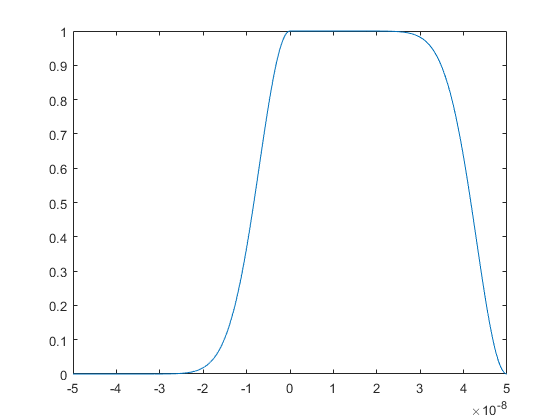

%fn2plot selects the array in the time base we want to plot
dampIndex = 9; % chooses which damping we are using
%stepR(1);
%fn2plot = interpVoltAllDbl(dampIndex,1:end-1);
fn2plot = gEdge;
f_LT_array = f;
plot(time,fn2plot);

## Fourier Transform

fn_FFT = fft(fn2plot)

fn_FFT = 	1.0e+03 *

   1.0000 + 0.0000i  -0.3212 + 0.5189i   0.0000 + 0.0000i  -0.1458 - 0.0041i   0.0000 + 0.0000i  -0.0301 - 0.0359i   0.0000 + 0.0000i  -0.0028 - 0.0149i   0.0000 + 0.0000i  -0.0001 - 0.0058i   0.0000 + 0.0000i  -0.0000 - 0.0028i   0.0000 + 0.0000i  -0.0000 - 0.0016i   0.0000 + 0.0000i  -0.0000 - 0.0010i   0.0000 + 0.0000i  -0.0000 - 0.0007i   0.0000 + 0.0000i  -0.0000 - 0.0005i   0.0000 + 0.0000i  -0.0000 - 0.0004i   0.0000 + 0.0000i  -0.0000 - 0.0003i   0.0000 + 0.0000i  -0.0000 - 0.0002i   0.0000 + 0.0000i  -0.0000 - 0.0002i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0001i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i


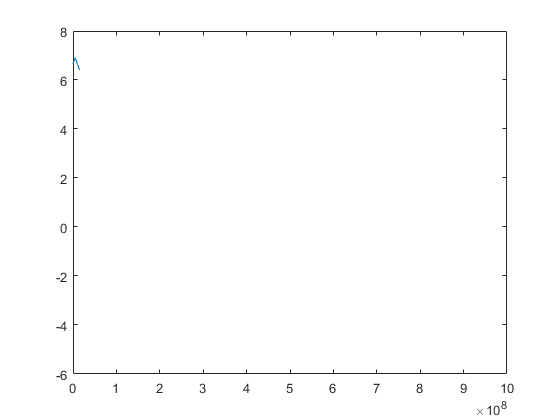

fn_FFT_normal = fftshift(fn_FFT);
plot(f_LT_array,log(abs(fn_FFT_normal)))
fmin = 0;
fmax = 1*c.giga;
xlim([fmin, fmax]);

% G_FFT = fft(Gaussian, n);
% P = abs(G_FFT/n);

## Get Mirror TF

## Convert COMSOL Transfer Function 

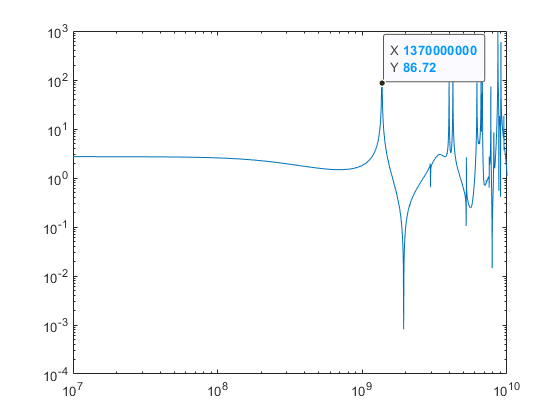

%addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
addpath('G:\My Drive\Code\Github Failed MATLAB 200807\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1');
filename='kimballCenterFieldTF_10MHz_10GHz.txt';
fileID=fopen(filename);
headers=textscan(fileID,'%s',1,'delimiter','\n','HeaderLines',8);
headers=char(headers{1});
fseek(fileID,0,'bof');
rawPoints=textscan(fileID,'%f','HeaderLines',9);
rawPoints=rawPoints{1};
rawPoints=rawPoints(4:end);
fclose(fileID);
freqIndex=strfind(headers,'=');
freqSteps=zeros(length(freqIndex),1);%sscanf(headers(timeIndex(1)+1:end),'%f');
for n=1:length(freqIndex)
    if freqIndex(n)<(length(headers)-20)
        freqSteps(n)=sscanf(headers(freqIndex(n)+1:freqIndex(n)+20),'%f',1);
    else
        freqSteps(n)=sscanf(headers(freqIndex(n)+1:end),'%f',1);
    end
end
fieldsVsFreq=zeros(length(rawPoints)/7,9); %time,Ex,Ey,Ez,|E|,Vport,Vnode
perpPlaneFieldRF=zeros(length(rawPoints)/7,1); %magnitude of field components in plane perpendicular to optical axis (y-z)
n=1;
k=1;
while k<=(length(rawPoints)/7)
    fieldsVsFreq(k,1)=freqSteps(n);
    fieldsVsFreq(k,2)=rawPoints(n); %ex
    fieldsVsFreq(k,3)=rawPoints(n+1); %ey
    fieldsVsFreq(k,4)=rawPoints(n+2); %ez
    fieldsVsFreq(k,5)=sqrt(fieldsVsFreq(k,2)^2+fieldsVsFreq(k,3)^2+fieldsVsFreq(k,4)^2); %e magnitude
    fieldsVsFreq(k,6)=rawPoints(n+3); %node 1 voltage
    fieldsVsFreq(k,7)=rawPoints(n+4); %ideal voltage supply
    fieldsVsFreq(k,8)=rawPoints(n+5); %node 2 voltage
    fieldsVsFreq(k,9)=rawPoints(n+6); %voltage at port
    perpPlaneFieldRF(k)=sqrt(abs(fieldsVsFreq(k,3))^2+abs(fieldsVsFreq(k,4))^2);
    n=n+7; 
    k=k+1;
end

% Look at transfer Function
loglog(fieldsVsFreq(:,1),abs(fieldsVsFreq(:,2)))

## Symmetrize Fields to Negative Frequencies

comsolFreqStep=fieldsVsFreq(2,1)-fieldsVsFreq(1,1)

comsolFreqStep = 10000000

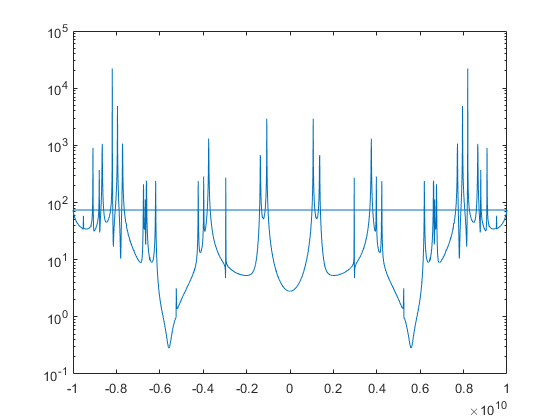

posFreq=fieldsVsFreq(:,1);
% posFreqPad=transpose((posFreq(end)+comsolFreqStep):comsolFreqStep:highestFreq);
% posFreq=[posFreq;posFreqPad];
negFreq=-1*flip(posFreq);
mirrorTFpos=(fieldsVsFreq(:,5)./fieldsVsFreq(:,9));%/length(posFreq);
% mirrorTFposPad=mirrorTFpos(end)*ones(length(posFreqPad),1);
mirrorTFpos=[mirrorTFpos];
mirrorTFneg=flip(conj(mirrorTFpos));
comsolFreq=[posFreq;negFreq];
mirrorTF=[mirrorTFpos;mirrorTFneg];
semilogy(comsolFreq,abs(mirrorTF))

## Compare Freq Vectors

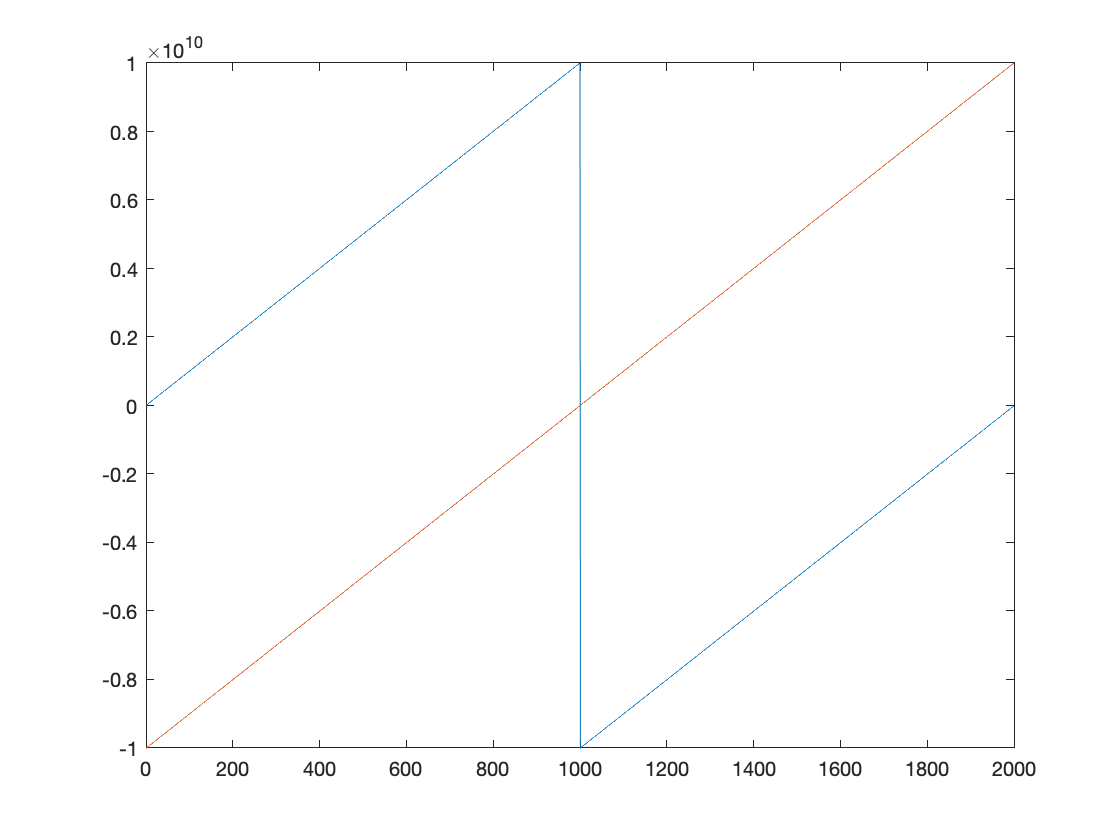

comsolFreqTranspose = comsolFreq.';
plot(comsolFreqTranspose);
hold on
plot(f_LT_array)

## Mix LTSpice and COMSOL Transfer Functions

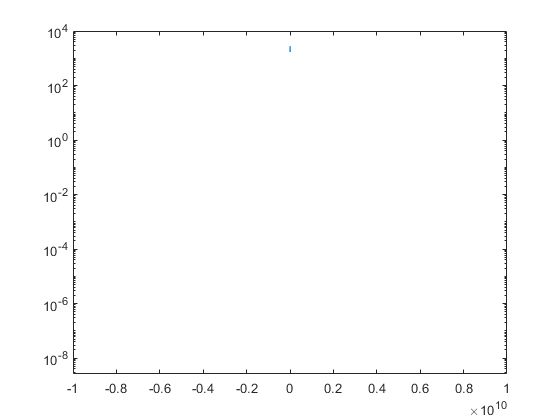

CombinedFreqResponse = (mirrorTF).'.*fn_FFT;
semilogy(f_LT_array, abs(fftshift(CombinedFreqResponse)))

## Inverse Fourier Transform

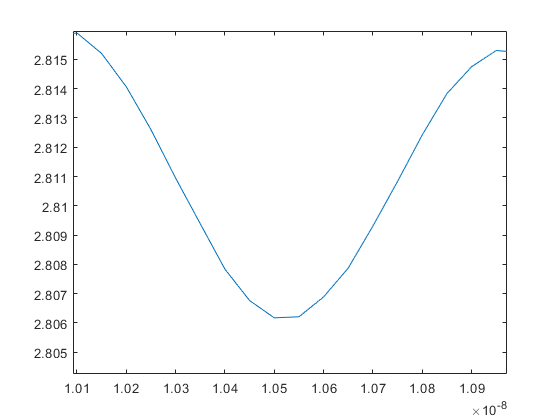

invFnFFT = ifft(CombinedFreqResponse);
plot(time,invFnFFT);

## Plotting Settings

% x0=0;
% y0=0;
% width=1000;
% height=750;
% 
% set(gcf,'position',[x0,y0,width,height])
% set(gcf,'DefaultLineLineWidth',3)
% set(gca,'FontSize',25)
% grid on;
% grid minor;
